clear; clc;

Seção inicial: definições do experimento para 4-QAM (QPSK)

% ranges de simulação
EbN0dB = 0:1:15;
EbN0 = 10.^(EbN0dB/10);
% Número de bits testados por amostra
Ns = 1e6;

% Vetores auxiliares para guardar os resultados
Pb = zeros(2, numel(EbN0dB)); % Probabilidade de erro (teórica)
BER = Pb; % Taxa de erro de bits (simulada)

item a: Mapeamento Natural

for ii = 1:numel(EbN0)
    N0 = 1./EbN0(ii); % considerando Eb = 1
    sigma = sqrt(N0/2);

    map = [0 0; 0 1; 1 0; 1 1];
    coords = [-1-1j; -1+1j; 1-1j; 1+1j];

    % rodando o experimento
    txBits = randi([0 1], 2*Ns, 1); % geram-se 2*Ns bits
    txIdxs = bi2de(reshape(txBits,2,[]).','left-msb'); % converte-se cada par de bits em seu decimal

    s = coords(txIdxs+1);
    n = sigma*(randn(Ns,1) + 1j*randn(Ns,1)); % noise
    r = s + n;

    % símbolos recebidos:
    % a fórmula abaixo calcula o índice de distância mínima à constelação
    [~,rxIdxs] = min(abs(r - coords.'),[],2); % retorna apenas o índice mínimo em cada linha
    % rxIdxs in {1,2,3,4}

    rxBits = reshape(map(rxIdxs,:).',[],1);

    % calculando resultados
    BER(1, ii) = mean(rxBits ~= txBits);
    Pb(1, ii) = qfunc(sqrt(2*EbN0(ii)));
end

item b: Mapeamento Gray

for ii = 1:numel(EbN0)
    N0 = 1./EbN0(ii); % considerando Eb = 1
    sigma = sqrt(N0/2);

    map = [0 0; 0 1; 1 1; 1 0];
    coords = [-1-1j; -1+1j; 1+1j; 1-1j];

    % rodando o experimento
    txBits = randi([0 1], 2*Ns, 1); % geram-se 2*Ns bits
    txIdxs = bi2de(reshape(txBits,2,[]).','left-msb'); % converte-se cada par de bits em seu decimal

    s = coords(txIdxs+1);
    n = sigma*(randn(Ns,1) + 1j*randn(Ns,1)); % noise
    r = s + n;

    % símbolos recebidos:
    [~,rxIdxs] = min(abs(r - coords.'),[],2); % retorna apenas o índice mínimo em cada linha
    % rxIdxs in {1,2,3,4}

    rxBits = reshape(map(rxIdxs,:).',[],1);

    % calculando resultados
    BER(2, ii) = mean(rxBits ~= txBits);
    Pb(2, ii) = qfunc(sqrt(2*EbN0(ii)));
end

Seção final: Plotando os gráficos:

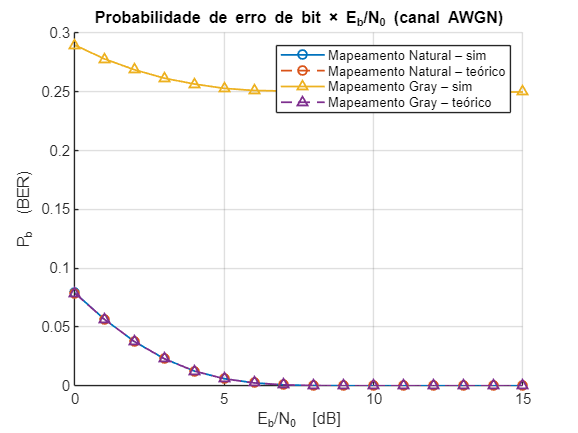

figure; hold on; grid on;
mods   = {'Mapeamento Natural','Mapeamento Gray'};
marks  = {'o','^'};

for m = 1:2
    semilogy(EbN0dB,BER(m,:),['-' marks{m}],'LineWidth',1.2);
    semilogy(EbN0dB,Pb (m,:),['--' marks{m}],'LineWidth',1.2);
end

xlabel('E_b/N_0  [dB]'); ylabel('P_b  (BER)');
legend( [strcat(mods,' – sim').', strcat(mods,' – teórico').'].', ...
    'Location','northeast');
title('Probabilidade de erro de bit × E_b/N_0 (canal AWGN)');